# 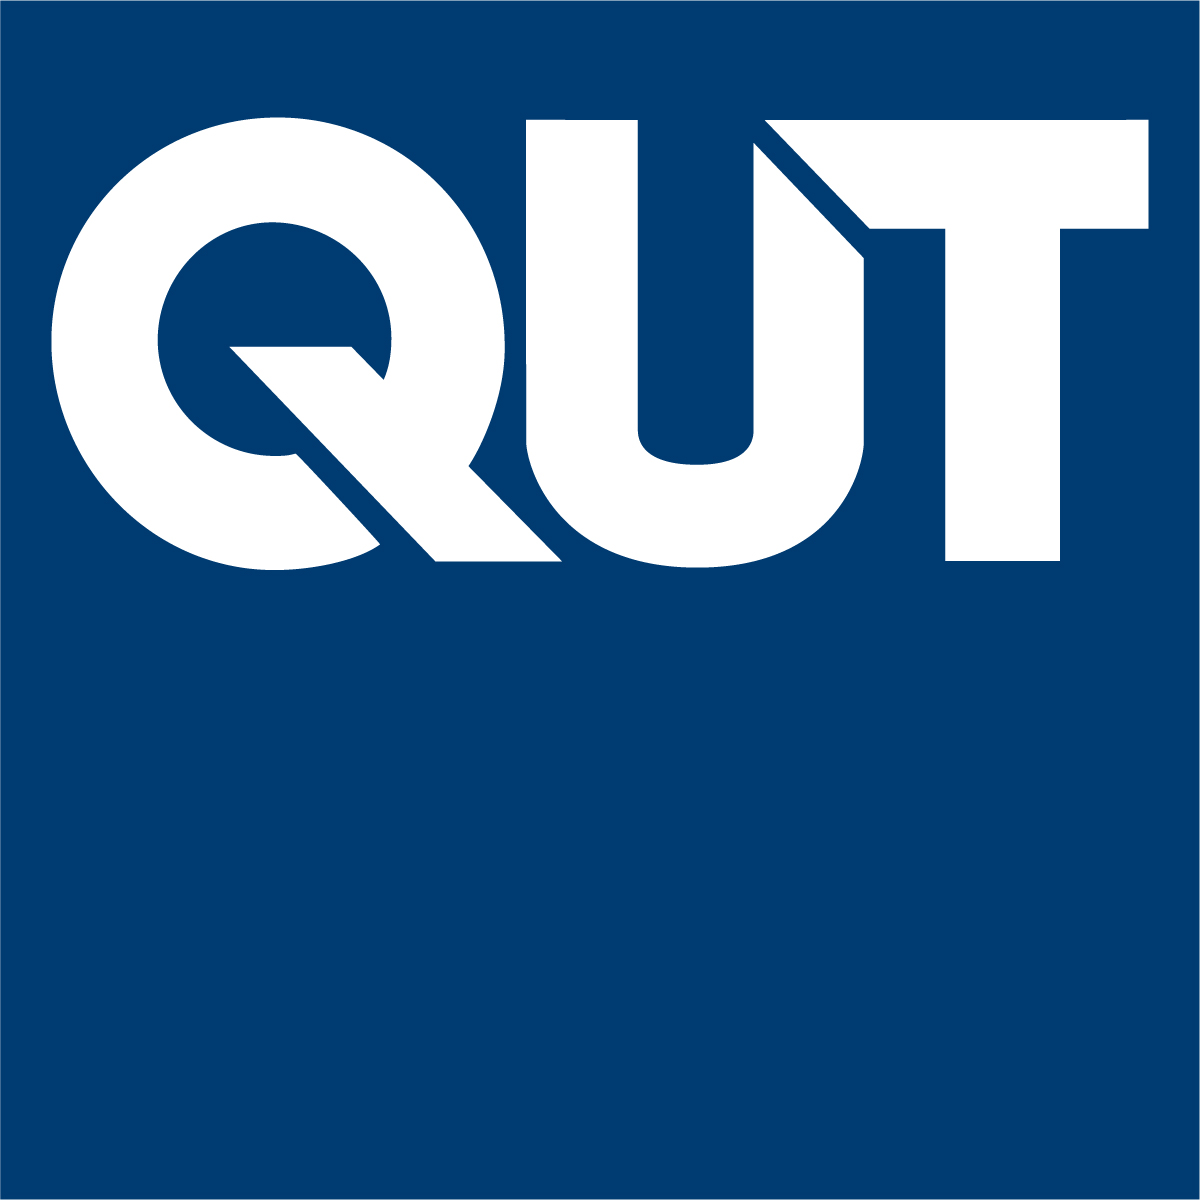

# MXB201 Chapter 2: Least Squares

Professor Tim Moroney,  2022

V1.0

## 2.1 Introduction

[Video](https://web.microsoftstream.com/video/7a80280d-1940-4fae-b10a-4329b448a58d)

In the previous chapter we considered the linear system $Ax = b$ and spent some time characterising the form of the solutions when the system is consistent.

Suppose though, that the system is *inconsistent*.  What then?  One option is to simply declare the problem inconsistent and leave it at that.

But perhaps we would like to proceed all the same, and try to find the "nearest thing" to a solution.  What would that look like?

A natural objective is to minimise the norm of the *residual*: $\|b - Ax\|$.  Although we cannot find $x$ such that $Ax = b$, we will nevertheless choose $x$ to make $Ax$ as close as possible to $b$, in the sense that

$x = \textrm{argmin}_{x^* \in \mathbb{R}^n} \|b - Ax^*\|$.    (1)

This minimisation problem is known as the **Least Squares** problem.

Notice how the least squares problem (1) nicely generalises the special case of solving $Ax = b$ for a consistent system.  For a consistent system, the solution to (1) would simply be the vector $x$ that minimised the residual norm $\|b-Ax\|$ by making it zero.  But (1) also has solutions for inconsistent systems $Ax = b$ where the residual norm cannot be made zero.

## 2.2 The geometric picture

While it might seem that the minimisation problem (1) would require techniques from calculus, in fact it can be handled entirely using linear algebra.  The key observation is that the residual norm $\|b - Ax\|$ will be smallest when the residual vector $b - Ax$ is *orthogonal* to the column space of $A$.

[Video](https://web.microsoftstream.com/video/3ea7b162-a30c-4f62-9284-0ee8cc50c342)

Here's the geometric picture

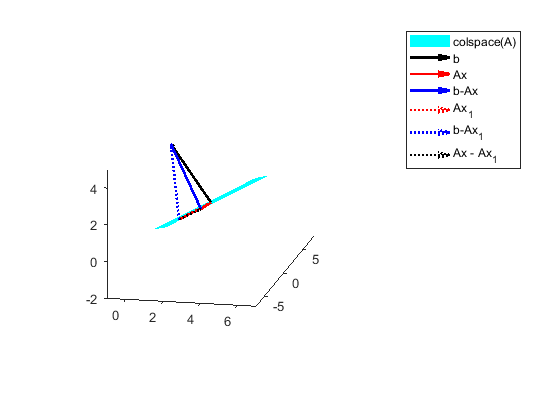

least_squares_pic

The cyan-coloured plane is the column space of $A$.  The vector in black is $b$.  We can see immediately that $b$ does not lie in the column space of $A$, indicating that there is no solution to $Ax = b$.

The vector in red, call it $b_P$, is the orthogonal projection of $b$ onto the column space, $b_P = \textrm{Proj}_{\textrm{colspace}(A)}(b)$.  Since it belongs to the column space, this vector is equal to $Ax$ for some $x$: $b_P = Ax$.  This $x$ will be the least squares solution.

The vector in blue is the residual vector, equal to $b - b_P = b - Ax$.  By construction, it is orthogonal to the column space.  (Rotate the image if you need to convince yourself you're seeing a right angle between the red and blue vectors.)

The *dotted* *red *vector is equal to $Ax_1$ for some *other* vector $x_1$.  We will argue that for any $x_1$, the residual $b - Ax_1$ (shown in dotted blue) has a larger norm than $b - Ax$.  In fact, the dotted blue vector is the hypotenuse of the right-angled triangle involving $b - Ax_1$ (dotted blue), $b-Ax$ (solid blue) and $Ax-Ax_1$ (dotted black).  Again, rotate the figure as needed if you want further convincing of this geometrically.

We are thus led to the following theorem, which we will now prove.

**Theorem**: The solution to equation (1) is obtained by the vector $x$ such that $b - Ax$ is orthogonal to the column space of $A$.

The proof relies on the Pythagorean Theorem in $\mathbb{R}^n$.  If you need a quick refresher on that, watch here.

[Video](https://web.microsoftstream.com/video/c0bd53c0-5960-49e2-9e4e-4631b5a9da4f)

Now for the proof.

[Video](https://web.microsoftstream.com/video/d091f955-f42c-455c-b069-45c9791832d3)

**Proof** [See also Anton Theorem 6.4.1]:

Where it's helpful we will refer to the vectors in diagram above, but this is not part of the argument, it's just for visual clarity.

Let $b_P$ (red solid) denote the vector obtained by projecting $b$ (black solid) orthogonally onto the column space of $A$.  That is, this vector $b_P = Ax$ for some vector $x$, and $b - b_p$ (blue solid) is orthogonal to the column space of $A$.

If $w$ (red dotted) is any other vector in the column space of $A$, we may write $b - w$ (blue dotted) as

$b - w$ = $b - b_P + b_P - w$

But $b_P - w$ (black dotted) belongs to the column space of $A$ (because $b_P$ and $w$ both do).  Meanwhile, as already noted, $b - b_P$ is orthogonal to the column space of $A$, and hence in particular it is orthogonal to $b_p - w$.  So the Pythagorean theorem applies, and hence


$$\|b - w\|^2 = \|b - b_P\|^2 + \|b_P - w\|^2$$


Since by assumption $b_P$ and $w$ are not the same vector, $\|b_P - w\|^2 > 0$, and so


$$\|b-w\|^2 > \|b - b_P\|^2$$


which also implies (since norms are nonnegative)

$\|b-w\| > \|b - b_P\|$.

The result is proved.  The minimum norm possible is $\|b - b_P\|$, and the least squares solution is obtained by choosing $x$ to satisfy $Ax = b_p$, with the residual vector $b - Ax = b - b_P$ being orthogonal to the column space of $A$.

#### Exercise

On a piece of paper, go through this same proof yourself by hand.  Don't refer to back to the example video or lecture notes unless you really get stuck.▫

## 2.3 The normal equations

[Video](https://web.microsoftstream.com/video/2cbf21d4-9fc7-4a0a-bb61-01df6617f069)

We recall from Chapter 1 that the null space of $A^T$ is orthogonal to the column space of $A$.  Hence, the statement that $b - Ax$ is orthogonal to the column space of $A$ is equivalent to the statement that $b - Ax$ belongs to the null space of $A^T$.  That gives us a simple formulation of the least squares problem in purely linear algebra terms: we want to find $x$ such that


$$A^T(b - Ax) = 0$$


Expanding, this is equivalent to solving

$A^TAx = A^T b$    (2)

Equation (2) is known as the **Normal Equations** (usually plural, for some reason).  Solving this equation obtains the least squares solution, satisfying (1).

Notice how equation (2) generalises the linear system $Ax = b$.  Solutions of $Ax = b$, if they exist, also satisfy (2).  But whereas $Ax = b$ can be inconsistent, equation (2) is always consistent.

## 2.4 Small example

Let's give it a go!  For the sake of simplicity, we'll start with a $3 \times 2$ example.  This is in fact the example illustrated in the diagram above.

[Video](https://web.microsoftstream.com/video/7cda3f54-ec64-4491-acb8-ffd10dffb99b)

#### Exercise

On a piece of paper, solve this same problem yourself by hand.  Don't refer to back to the example video unless you really get stuck.▫

Now in MATLAB.

A = sym([8 1 ; -1 6 ; -2 3]), b = sym([4; -3; 2])

$$A = \left(\begin{array}{cc} 8 & 1\\ -1 & 6\\ -2 & 3 \end{array}\right)$$

$$b = \left(\begin{array}{c} 4\\ -3\\ 2 \end{array}\right)$$

We can *try* to solve $Ax = b$, but prepare to be disappointed.

rref2([A b])

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

We see that $\textrm{rank}(A) = 2$ but $\textrm{rank}([A|b]) = 3$.  There is no solution to$Ax = b$.

So instead let's find the vector $x$ that minimises the residual norm $\|b - Ax\|$.

We form the normal equations:

ATA = A' * A, ATb = A' * b

$$ATA = \left(\begin{array}{cc} 69 & -4\\ -4 & 46 \end{array}\right)$$

$$ATb = \left(\begin{array}{c} 31\\ -8 \end{array}\right)$$

Notice that the matrix $A^T A$ is *symmetric* by construction.

Now, the normal equations are *guaranteed *to be consistent for any vector $b$, so we proceed with RREF for the normal equations.

R = rref2([ATA ATb])

$$R = \left(\begin{array}{ccc} 1 & 0 & \frac{697}{1579}\\ 0 & 1 & -\frac{214}{1579} \end{array}\right)$$

The solution is

x = R(:, end)

$$x = \left(\begin{array}{c} \frac{697}{1579}\\ -\frac{214}{1579} \end{array}\right)$$

In summary, the vector $x$ that we found does *not* solve $Ax = b$, but rather it solves $x = \textrm{argmin}_{x^* \in \mathbb{R}^n} \|b - Ax^*\|$.  We can calculate what this minimal residual norm is.

norm(b - A*x), double(ans)

$$ans = \frac{\sqrt{1579}\,\sqrt{22472}}{1579}$$

ans = 3.7725

Just for fun, we could try perturbing $x$ a little bit, and confirming that the residual norm increases.

norm(b - A*(x + 0.05*randn(size(x)))); double(ans)

ans = 3.9034

#### Exercise

In a (separate) MATLAB editor tab, solve this same problem yourself.  Don't refer to back to the example code unless you really get stuck.▫

## 2.5 Orthogonal projection and orthogonal projectors

[Video](https://web.microsoftstream.com/video/a07ba248-0e9c-4665-af7f-0c4ecf476833)

Our geometric picture of the least squares problem and subsequent derivation of the normal equations made use of the orthogonal projection of a vector onto the column space of $A$.  Recall our earlier diagram, where this vector was illustrated in red.  If we wanted to compute this vector $b_P = \textrm{Proj}_{\textrm{colspace}(A)}(b)$ explicitly, how would we do so?  In fact, we have essentially solved this problem already.  The orthogonal projection is simply the vector $Ax$, where $x$ is the solution of the normal equations $A^TAx = A^T b$.  Rearranging, we have


$$x = (A^TA)^{-1}A^T b$$


and hence

$b_P = \textrm{Proj}_{\textrm{colspace}(A)}(b) =  Ax = A(A^TA)^{-1}A^T b$.

We can identify the matrix


$$P = A(A^TA)^{-1}A^T$$


as the *orthogonal projector* onto the column space of $A$.  It operates on (i.e. multiplies) an arbitrary vector $b$ to produce $Pb = \textrm{Proj}_{\textrm{colspace}(A)}(b)$.

Let's calculate the orthogonal projector for the example above.

P = A*inv(ATA)*A'

$$P = \left(\begin{array}{ccc} \frac{3077}{3158} & \frac{117}{1579} & -\frac{441}{3158}\\ \frac{117}{1579} & \frac{1241}{1579} & \frac{637}{1579}\\ -\frac{441}{3158} & \frac{637}{1579} & \frac{757}{3158} \end{array}\right)$$

From its definition we can see that the orthogonal projector is symmetric.  Verifying for this example:

isequal(P', P)

ans = logical
   1

Multiplying this matrix $P$ by the vector $b$ for the problem above produces its orthogonal projection onto the column space of $A$.

bP = P * b

$$bP = \left(\begin{array}{c} \frac{5362}{1579}\\ -\frac{1981}{1579}\\ -\frac{2036}{1579} \end{array}\right)$$

By construction, this vector is in the column space of $A$.  So if we wanted, we could solve $Ax = b_P$ for this right hand side.  What solution $x$ should we expect?  Let's do the RREF to confirm consistency.

R = rref([A bP])

$$R = \left(\begin{array}{ccc} 1 & 0 & \frac{697}{1579}\\ 0 & 1 & -\frac{214}{1579}\\ 0 & 0 & 0 \end{array}\right)$$

We see that $\textrm{rank}(A) = \textrm{rank}([A \ b_P] = 2 = n$ so we have a unique solution.

x2 = R(1:2, end)

$$x2 = \left(\begin{array}{c} \frac{697}{1579}\\ -\frac{214}{1579} \end{array}\right)$$

We can verify that we've just obtained the least squares solution again.

isequal(x, x2)

ans = logical
   1

If the least squares solution is all you need, this is a very roundabout way of getting it.  Better to just solve the normal equations.

#### Exercise

In a (separate) MATLAB editor tab, find the orthogonal projector $P$ for this same problem yourself.  Don't refer to back to the example code unless you really get stuck.▫

Incidentally, what should $P^2$ equal?  Remember, by definition, the product $Pb$ produces the orthogonal projection $b_P = \textrm{Proj}_{\textrm{colspace}(A)}(b)$.  So applying $P$ a *second time* would be applying $P$ to the orthogonal projection $b_P$.  Since $b_P$ is already in the column space, the orthogonal projection of $b_P$ onto that space is $b_P$ itself.  Hence we have


$$P^2\, b = P\, P b = P\, b_P = b_P$$


In summary, $P b = b_P$ and also $P^2\, b = b_P$.  This is true for any $b$, hence we conclude that the orthogonal projector satisfies

$P^2 = P$.

A matrix with such a property is called *idempotent*.

Let's confirm.

isequal(P^2, P)

ans = logical
   1

All symmetric idempotent matrices are orthogonal projectors, and vice versa.

## 2.6 Dependent columns

Let's consider another example, which illustrates a possible pitfall when $A$ has dependent columns.

[Video](https://web.microsoftstream.com/video/73dd1ab1-ca6b-4491-aa8d-04fa1a67fe95)

#### Exercise

On a piece of paper, find the general solution to this same least squares problem yourself by hand.  Don't refer to back to the example video unless you really get stuck.▫

For a larger example of this scenario that we can do in MATLAB, let's revisit the rectangular matrix from Chapter 1, Section 1.4.

clear
m = 8;
n = 5;
A = sym([1    -1     0     1     0
         1     0     1    -3    -4
         2     2     4     0    -2
         1     0     1     2     1
         3     3     6     0    -3
         0     2     2     2     2
         0     1     1     4     4
         3    -2     1     2    -1])

$$A = \left(\begin{array}{ccccc} 1 & -1 & 0 & 1 & 0\\ 1 & 0 & 1 & -3 & -4\\ 2 & 2 & 4 & 0 & -2\\ 1 & 0 & 1 & 2 & 1\\ 3 & 3 & 6 & 0 & -3\\ 0 & 2 & 2 & 2 & 2\\ 0 & 1 & 1 & 4 & 4\\ 3 & -2 & 1 & 2 & -1 \end{array}\right)$$

In Chapter 1, we considered the right hand side

b1 = colspace(A) * [3;1;4]

$$b1 = \left(\begin{array}{c} 3\\ 1\\ 4\\ \frac{22}{7}\\ 6\\ \frac{2}{7}\\ \frac{10}{7}\\ \frac{58}{7} \end{array}\right)$$

We were able to solve $Ax = b_1$ with this right hand side, because it lies in the column space of $A$.  The RREF confirms thak $\textrm{rank}(A) = \textrm{rank}([A|b_1]) = 3$.

rref([A b1])

$$ans = \left(\begin{array}{cccccc} 1 & 0 & 1 & 0 & -1 & \frac{16}{7}\\ 0 & 1 & 1 & 0 & 0 & -\frac{2}{7}\\ 0 & 0 & 0 & 1 & 1 & \frac{3}{7}\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

On the other hand, for a vector $b_2$ not in the column space of $A$, there is no solution to $Ax = b_2$.  We will find that $\textrm{rank}(A) \neq \textrm{rank}([A|b_2]) $.  For example

b2 = sym((1:8)')

$$b2 = \left(\begin{array}{c} 1\\ 2\\ 3\\ 4\\ 5\\ 6\\ 7\\ 8 \end{array}\right)$$

rref2([A b2])

$$ans = \left(\begin{array}{cccccc} 1 & 0 & 1 & 0 & -1 & 0\\ 0 & 1 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

We see that $\textrm{rank}(A) = 3$ but $\textrm{rank}([A|b_2]) = 4$.  We cannot solve $Ax = b_2$.  But we *can *solve the least squares problem: $x = \textrm{argmin}_{x^* \in \mathbb{R}^n} \|b_2 - Ax^*\|$.

We form the normal equations:

ATA = A' * A, ATb2 = A' * b2

$$ATA = \left(\begin{array}{ccccc} 25 & 6 & 31 & 6 & -19\\ 6 & 23 & 29 & 3 & -3\\ 31 & 29 & 60 & 9 & -22\\ 6 & 3 & 9 & 38 & 32\\ -19 & -3 & -22 & 32 & 51 \end{array}\right)$$

$$ATb2 = \left(\begin{array}{c} 52\\ 23\\ 75\\ 59\\ 7 \end{array}\right)$$

As always, $A^TA$ is a symmetric matrix.

isequal(ATA', ATA)

ans = logical
   1


The normal equations are guaranteed consistent for any vector $b_2$, so we proceed as usual with RREF.

[R, ~, bv] = rref2([ATA ATb2])

$$R = \left(\begin{array}{cccccc} 1 & 0 & 1 & 0 & -1 & \frac{6614}{3929}\\ 0 & 1 & 1 & 0 & 0 & \frac{7801}{19645}\\ 0 & 0 & 0 & 1 & 1 & \frac{24664}{19645}\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

bv =      1     2     4


Ah, but look here.  What have we found?  The pivots are in columns 1,2 and 4.  Hence, the basic variables are $x_1$, $x_2$ and $x_4$.  This leaves $x_3$ and $x_5$ as free variables.  So in fact the normal equations for this example have *infinitely many solutions.*  There is a two-parameter family of solutions to this least squares problem, rather than a unique solution.

### 2.6.1 Infinitely many solutions

One particular least squares solution can be read off the RREF, keeping in mind which are the basic variables, and which are the free variables.

x_p = sym(zeros(5,1));
x_p(bv) = R(1:3, end)

$$x\_p = \left(\begin{array}{c} \frac{6614}{3929}\\ \frac{7801}{19645}\\ 0\\ \frac{24664}{19645}\\ 0 \end{array}\right)$$

As usual, this is also the solution returned by MATLAB's backslash:

ATA \ ATb2

$$ans = \left(\begin{array}{c} \frac{6614}{3929}\\ \frac{7801}{19645}\\ 0\\ \frac{24664}{19645}\\ 0 \end{array}\right)$$

To find the general solution, we find the nullspace of $A^TA$.  Equivalently, this is also just the nullspace of $A$ itself.

NS = null(ATA)

$$NS = \left(\begin{array}{cc} -1 & 1\\ -1 & 0\\ 1 & 0\\ 0 & -1\\ 0 & 1 \end{array}\right)$$

We remember from Chapter 1, the general solution is given by the sum of any particular solution plus a general vector from the null space.

t = sym('t', [2,1], 'real')

$$t = \left(\begin{array}{c} t_{1}\\ t_{2} \end{array}\right)$$

x_general = x_p + NS * t

$$x\_general = \left(\begin{array}{c} t_{2}-t_{1}+\frac{6614}{3929}\\ \frac{7801}{19645}-t_{1}\\ t_{1}\\ \frac{24664}{19645}-t_{2}\\ t_{2} \end{array}\right)$$

For any values of $t_1$ and $t_2$ this solution produces the minimal possible norm of $\|b - Ax\|$.  Let's confirm that the same value is attained, no matter the values of $t_1$ and $t_2$.

norm(b2 - A*x_general)

$$ans = \frac{\sqrt{19645}\,\sqrt{653341}}{19645}$$

The minimal norm is independent of the parameter values $t_1$ and $t_2$.

#### Exercise

In a (separate) MATLAB editor tab, find the general solution to this same least squares problem yourself.  Don't refer to back to the example code unless you really get stuck.▫

### 2.6.2 Recovering a unique solution

In this case, we could have done without columns 3 and 5 of $A$, since they correspond to non-basic columns (free variables in our solution).  Let's form a new matrix $W$ with just the basic columns of $A$.  The columns of $W$ then form a basis for the column space of $A$.

W = A(:, bv)  % bv = [1 2 4]

$$W = \left(\begin{array}{ccc} 1 & -1 & 1\\ 1 & 0 & -3\\ 2 & 2 & 0\\ 1 & 0 & 2\\ 3 & 3 & 0\\ 0 & 2 & 2\\ 0 & 1 & 4\\ 3 & -2 & 2 \end{array}\right)$$

We get a unique least squares solution this time (it's just the particular solution $x_p$ from above, but without the zero entries for the free variables)

x = (W'*W) \ (W' * b2)

$$x = \left(\begin{array}{c} \frac{6614}{3929}\\ \frac{7801}{19645}\\ \frac{24664}{19645} \end{array}\right)$$

with the same, minimal possible, norm as before.

norm(b2 - W*x)

$$ans = \frac{\sqrt{19645}\,\sqrt{653341}}{19645}$$

### 2.6.3 Orthogonal projector onto the column space

We can also compute the orthogonal projector onto the column space of $A$, now that we have our basis in $W$.

[Video](https://web.microsoftstream.com/video/c23a8fa5-e6b9-4741-ad69-5cd8684de5fa)

And here's the larger MATLAB example:

P = W*inv(W'*W)*W'

$$P = \left(\begin{array}{cccccccc} \frac{2576}{19645} & -\frac{419}{19645} & -\frac{416}{19645} & \frac{1871}{19645} & -\frac{624}{19645} & -\frac{282}{3929} & \frac{669}{19645} & \frac{6107}{19645}\\ -\frac{419}{19645} & \frac{6436}{19645} & \frac{2264}{19645} & -\frac{2249}{19645} & \frac{3396}{19645} & -\frac{732}{3929} & -\frac{7041}{19645} & \frac{387}{19645}\\ -\frac{416}{19645} & \frac{2264}{19645} & \frac{5436}{19645} & \frac{674}{19645} & \frac{8154}{19645} & \frac{436}{3929} & \frac{136}{19645} & \frac{478}{19645}\\ \frac{1871}{19645} & -\frac{2249}{19645} & \frac{674}{19645} & \frac{2541}{19645} & \frac{1011}{19645} & \frac{268}{3929} & \frac{3544}{19645} & \frac{4367}{19645}\\ -\frac{624}{19645} & \frac{3396}{19645} & \frac{8154}{19645} & \frac{1011}{19645} & \frac{12231}{19645} & \frac{654}{3929} & \frac{204}{19645} & \frac{717}{19645}\\ -\frac{282}{3929} & -\frac{732}{3929} & \frac{436}{3929} & \frac{268}{3929} & \frac{654}{3929} & \frac{1100}{3929} & \frac{1150}{3929} & -\frac{696}{3929}\\ \frac{669}{19645} & -\frac{7041}{19645} & \frac{136}{19645} & \frac{3544}{19645} & \frac{204}{19645} & \frac{1150}{3929} & \frac{9226}{19645} & \frac{648}{19645}\\ \frac{6107}{19645} & \frac{387}{19645} & \frac{478}{19645} & \frac{4367}{19645} & \frac{717}{19645} & -\frac{696}{3929} & \frac{648}{19645} & \frac{14989}{19645} \end{array}\right)$$

isequal(P', P), isequal(P^2, P)  % just sanity-checking!

ans = logical
   1


ans = logical
   1


Recall that we initially were considering two right hand side vectors, $b_1$ and $b_2$.  Only the first, $b_1$ was in the column space of $A$.

b1

$$b1 = \left(\begin{array}{c} 3\\ 1\\ 4\\ \frac{22}{7}\\ 6\\ \frac{2}{7}\\ \frac{10}{7}\\ \frac{58}{7} \end{array}\right)$$

What should we expect the product $Pb_1$ to equal?

P*b1

$$ans = \left(\begin{array}{c} 3\\ 1\\ 4\\ \frac{22}{7}\\ 6\\ \frac{2}{7}\\ \frac{10}{7}\\ \frac{58}{7} \end{array}\right)$$

$Pb_1$ is the orthogonal projection of $b_1$ onto the column space of $A$.  Hence, $Pb_1 = b_1$.

isequal(P*b1, b1)

ans = logical
   1

On the other hand, $b_2$ is not in the column space, so $Pb_2 \neq b_2$.

proj_b2_on_CS = P*b2

$$proj\_b2\_on\_CS = \left(\begin{array}{c} \frac{49933}{19645}\\ -\frac{40922}{19645}\\ \frac{81742}{19645}\\ \frac{82398}{19645}\\ \frac{122613}{19645}\\ \frac{12986}{3929}\\ \frac{106457}{19645}\\ \frac{132936}{19645} \end{array}\right)$$

The general solution $x$ we obtained above to the least squares problem satisfies $Ax = Pb_2$.

isequal(A*x_general, P*b2)

ans = logical
   1

### 2.6.4 When linearly dependent columns could be a mistake

Depending on the application, having a non-unique solution to the least squares problem might be a nuisance.  This is why in statistics for example, you are taught not to include linearly dependent explanatory variables (columns) in the regression design matrix.  Doing so leads to an infinite family of possible least squares solutions rather than a single "line of best fit".  Depending on the algorithm being used, the software might simply fail with an error (or worse, return an erroneous solution) under these conditions.

[Video](https://web.microsoftstream.com/video/ed592216-4fd4-475f-a09a-ab0ecef07e22)

## 2.7 Orthogonal projectors onto other spaces

### 2.7.1 Left null space

A key finding from Chapter 1 is that for a matrix $A \in \mathbb{R}^{m \times n}$, the column space and the left null space are orthogonal complements in $\mathbb{R}^m$.  This means that every vector $v \in \mathbb{R}^m$ can be decomposed uniquely as the sum of its projection onto the column space of $A$, and its projection onto the null space of $A^T$.

What then, is a matrix representation of the orthogonal projector onto $\textrm{nullspace}(A^T)$?  Certainly, we could generate a basis for this space as per our experience from Chapter 1.

[Video](https://web.microsoftstream.com/video/5610fe77-7171-4c97-a515-c97b16836a6f)

Here's the larger example in MATLAB.

LNS = null(A')

$$LNS = \left(\begin{array}{ccccc} -\frac{5}{7} & 0 & \frac{4}{7} & -\frac{1}{7} & -\frac{17}{7}\\ \frac{3}{7} & 0 & \frac{6}{7} & \frac{9}{7} & -\frac{1}{7}\\ -\frac{5}{14} & -\frac{3}{2} & -\frac{5}{7} & -\frac{4}{7} & -\frac{3}{14}\\ 1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

Notationally, since we used $P$ for the orthogonal projector onto $\textrm{colspace}(A)$, we'll use $Q$ to denote the orthogonal projector onto its orthogonal complement, which is $\textrm{nullspace}(A^T)}$.

Q = LNS*inv(LNS'*LNS)*LNS'

$$Q = \left(\begin{array}{cccccccc} \frac{17069}{19645} & \frac{419}{19645} & \frac{416}{19645} & -\frac{1871}{19645} & \frac{624}{19645} & \frac{282}{3929} & -\frac{669}{19645} & -\frac{6107}{19645}\\ \frac{419}{19645} & \frac{13209}{19645} & -\frac{2264}{19645} & \frac{2249}{19645} & -\frac{3396}{19645} & \frac{732}{3929} & \frac{7041}{19645} & -\frac{387}{19645}\\ \frac{416}{19645} & -\frac{2264}{19645} & \frac{14209}{19645} & -\frac{674}{19645} & -\frac{8154}{19645} & -\frac{436}{3929} & -\frac{136}{19645} & -\frac{478}{19645}\\ -\frac{1871}{19645} & \frac{2249}{19645} & -\frac{674}{19645} & \frac{17104}{19645} & -\frac{1011}{19645} & -\frac{268}{3929} & -\frac{3544}{19645} & -\frac{4367}{19645}\\ \frac{624}{19645} & -\frac{3396}{19645} & -\frac{8154}{19645} & -\frac{1011}{19645} & \frac{7414}{19645} & -\frac{654}{3929} & -\frac{204}{19645} & -\frac{717}{19645}\\ \frac{282}{3929} & \frac{732}{3929} & -\frac{436}{3929} & -\frac{268}{3929} & -\frac{654}{3929} & \frac{2829}{3929} & -\frac{1150}{3929} & \frac{696}{3929}\\ -\frac{669}{19645} & \frac{7041}{19645} & -\frac{136}{19645} & -\frac{3544}{19645} & -\frac{204}{19645} & -\frac{1150}{3929} & \frac{10419}{19645} & -\frac{648}{19645}\\ -\frac{6107}{19645} & -\frac{387}{19645} & -\frac{478}{19645} & -\frac{4367}{19645} & -\frac{717}{19645} & \frac{696}{3929} & -\frac{648}{19645} & \frac{4656}{19645} \end{array}\right)$$

The orthogonal projection of $b_2$ onto $\textrm{nullspace}(A^T)$ would then be

proj_b2_on_LNS = Q * b2

$$proj\_b2\_on\_LNS = \left(\begin{array}{c} -\frac{30288}{19645}\\ \frac{80212}{19645}\\ -\frac{22807}{19645}\\ -\frac{3818}{19645}\\ -\frac{24388}{19645}\\ \frac{10588}{3929}\\ \frac{31058}{19645}\\ \frac{24224}{19645} \end{array}\right)$$

And we can confirm two facts.  First, that the two projections we just calculated are orthogonal.

dot(proj_b2_on_CS, proj_b2_on_LNS)

$$ans = 0$$

Second, that they do indeed sum to $b_2$.

isequal(b2, proj_b2_on_CS + proj_b2_on_LNS)

ans = logical
   1

But this last fact shows us that we did too much work!  Since we know that the two projections sum to $b$, the once we know the orthogonal projector $P$, then $Q$ must simply be


$$Q = I - P$$


so that


$$P b + Q b = b$$


for any vector $b$.  Let's confirm:

isequal(Q, eye(size(P)) - P)

ans = logical
   1

In summary, if you have built the orthogonal projector $P$ onto some space, then the orthogonal projector onto its orthogonal complement is just $Q = I - P$.

#### Exercise

In a (separate) MATLAB editor tab, find the orthogonal projectors onto the column space and left null space of $A$ yourself.  Verify that they sum to the identity.  Don't refer to back to the example code unless you really get stuck.▫

### 2.7.2 Row space and null space

Analogously, if we wanted the orthogonal projectors onto the row and null spaces of $A$, we'd just need to find one of them, call it $P$, and get the other by $Q = I - P$.

We did actually calculate the null space of $A$ earlier:

NS

$$NS = \left(\begin{array}{cc} -1 & 1\\ -1 & 0\\ 1 & 0\\ 0 & -1\\ 0 & 1 \end{array}\right)$$

So the orthogonal projector onto the null space is given by

P = NS*inv(NS'*NS)*NS'

$$P = \left(\begin{array}{ccccc} \frac{1}{2} & \frac{1}{4} & -\frac{1}{4} & -\frac{1}{4} & \frac{1}{4}\\ \frac{1}{4} & \frac{3}{8} & -\frac{3}{8} & \frac{1}{8} & -\frac{1}{8}\\ -\frac{1}{4} & -\frac{3}{8} & \frac{3}{8} & -\frac{1}{8} & \frac{1}{8}\\ -\frac{1}{4} & \frac{1}{8} & -\frac{1}{8} & \frac{3}{8} & -\frac{3}{8}\\ \frac{1}{4} & -\frac{1}{8} & \frac{1}{8} & -\frac{3}{8} & \frac{3}{8} \end{array}\right)$$

The orthogonal projector $Q$ onto the row space, is then simply

Q = eye(size(P)) - P

$$Q = \left(\begin{array}{ccccc} \frac{1}{2} & -\frac{1}{4} & \frac{1}{4} & \frac{1}{4} & -\frac{1}{4}\\ -\frac{1}{4} & \frac{5}{8} & \frac{3}{8} & -\frac{1}{8} & \frac{1}{8}\\ \frac{1}{4} & \frac{3}{8} & \frac{5}{8} & \frac{1}{8} & -\frac{1}{8}\\ \frac{1}{4} & -\frac{1}{8} & \frac{1}{8} & \frac{5}{8} & \frac{3}{8}\\ -\frac{1}{4} & \frac{1}{8} & -\frac{1}{8} & \frac{3}{8} & \frac{5}{8} \end{array}\right)$$

The fundamental subspaces of a matrix are of great importance, obviously.  But the procedure we described for finding orthogonal projectors isn't tied to these particular subspaces.  For *any* vector space $\mathcal{V} \subset \mathcal{R}^n$, if $W$ is the matrix of basis vectors for that space, then the orthogonal projector $P$ onto the space is given by $P = W(W^T W)^{-1} W^T$, and the orthogonal projector $Q$ onto its orthogonal complement $\mathcal{V}^\perp$ is given by $Q = I - P$.

#### Exercise

In a (separate) MATLAB editor tab, find the orthogonal projectors onto the row space and null space of $A$ yourself.  Verify that they sum to the identity.  Don't refer to back to the example code unless you really get stuck.▫

## **2.8 Summary**

- The least squares problem $x = \textrm{argmin}_{x^* \in \mathbb{R}^n} \|b - Ax^*\|$ generalises the linear system problem $Ax = b$.

-     The former is always consistent, having either one solution or infinitely many solutions.

-     If the latter is consistent, its solutions also solve the former by making the residual norm zero.

- Solutions to the least squares problem can found by solving the normal equations $A^TAx = A^T b$.

- If the columns of a matrix $W$ are the basis vectors for a vector space $\mathcal{V} \subset \mathbb{R}^n$, then

-     The orthogonal projector onto $\mathcal{V}$ is given by $P = W(W^T W)^{-1} W^T$.

-     The orthogonal projector onto $\mathcal{V}^\perp$, the orthogonal complement of $V$, is given by $Q = I - P$.